# Get the RMS values

galaxies = ["NGC3198", 
    "NGC2841",
    "NGC2955",
    "NGC2403",
    "NGC4389",
    "NGC6015",
    "NGC7793",
    "NGC6946",
    "NGC4013", 
    "NGC3521",
    "NGC7331",
    "UGC11914",
    "UGC02487",
    "UGC02953",
    "UGC09133",
    "UGC05253",
    "UGC06787",
    "UGC03205",
    "UGC06786",
    "UGC03580",
    "UGC02916",
    "UGC08699"];

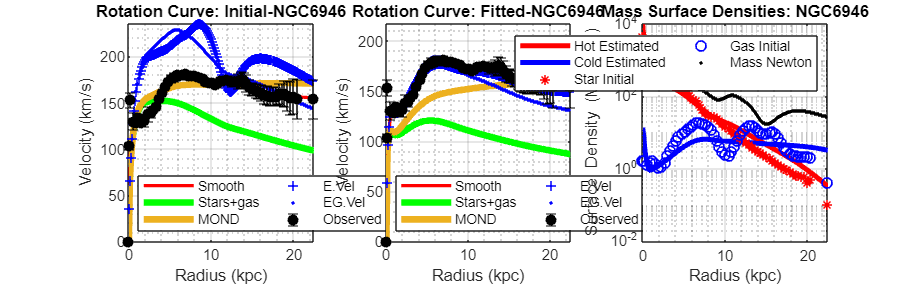

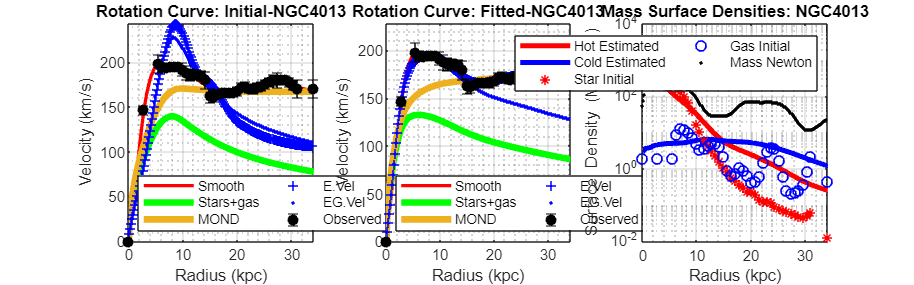

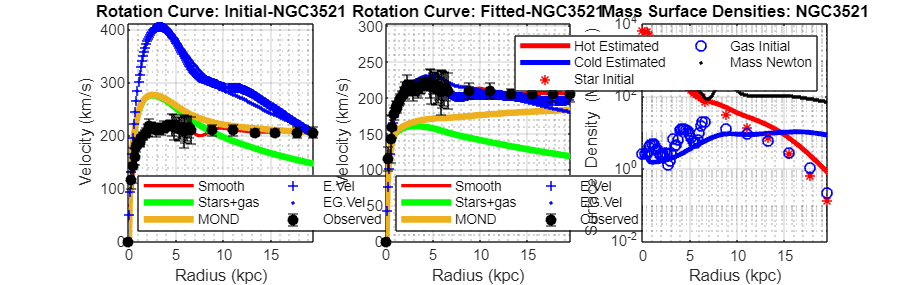

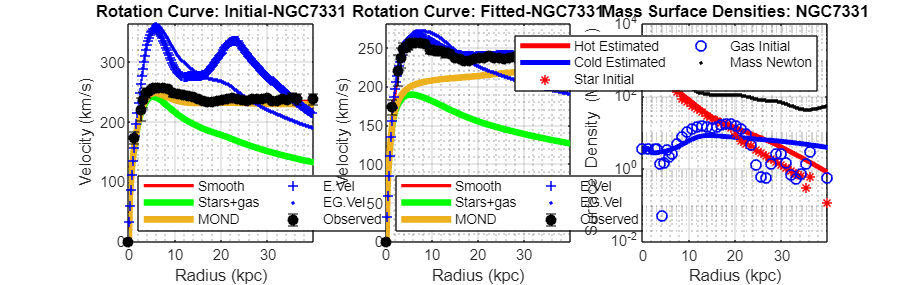

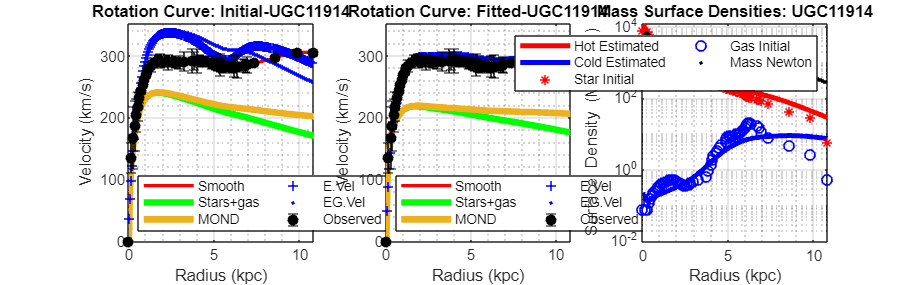

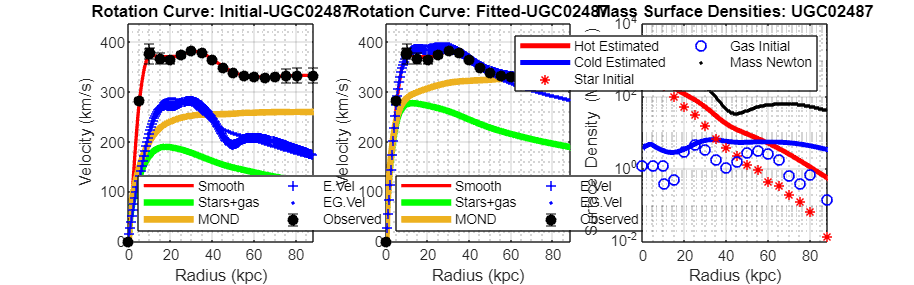

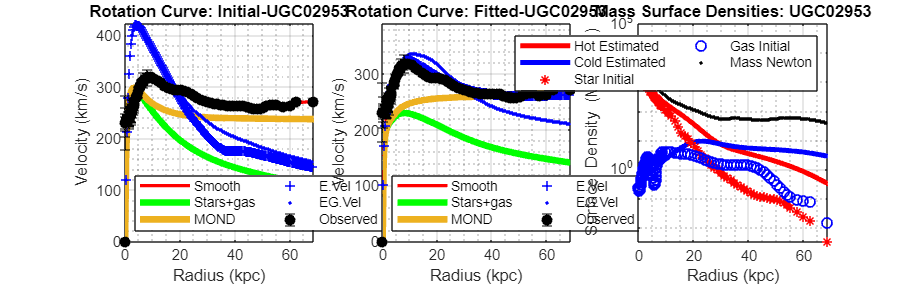

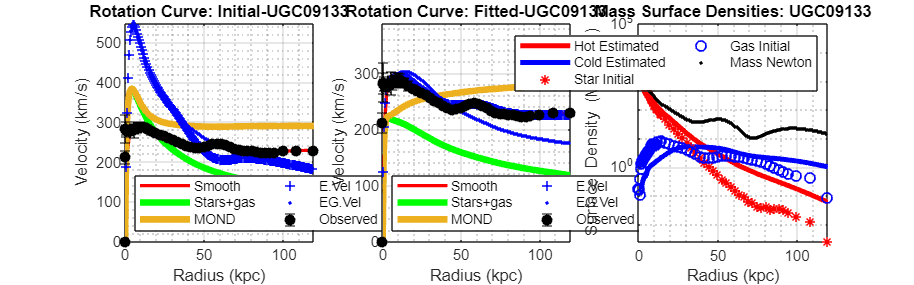

%% Looping trough all galaxies
O_RMS_Newton = zeros(size(galaxies));
O_RMS_MOND = zeros(size(galaxies));
O_RMS_EG = zeros(size(galaxies));
RMS_Newton = zeros(size(galaxies));
RMS_MOND = zeros(size(galaxies));
RMS_EG = zeros(size(galaxies));
O_MAD_Newton = zeros(size(galaxies));
O_MAD_MOND = zeros(size(galaxies));
O_MAD_EG = zeros(size(galaxies));
MAD_Newton = zeros(size(galaxies));
MAD_MOND = zeros(size(galaxies));
MAD_EG = zeros(size(galaxies));
V_MOND = [];
V_tot = [];
totGalaxyMass = zeros(length(galaxies),6);
for (gal = 1:length(galaxies))
    load(append(galaxies(gal),"103_200b.mat"));
    
    Rden = 1000*profile(:,1);
    StarDen = profile(:,2);
    integrand = 2 * pi * Rden .* StarDen;
    totMassS = trapz(Rden, integrand);
    
    StarDen = profile(:,11);
    integrand = 2 * pi * Rden .* StarDen;
    totMassS_2 = trapz(Rden, integrand);
    
    
    GasDen = profile(:,3);
    integrand = 2 * pi * Rden .* GasDen;
    totMassG = trapz(Rden, integrand);
    
    Rden = 1000*r_model;
    integrand = 2 * pi * Rden .* NSigma_S;
    totEstMASS_S = trapz(Rden, integrand);
    
    integrand = 2 * pi * Rden .* NSigma_H;
    totEstMASS_G = trapz(Rden, integrand);

    integrand = 2 * pi * Rden .* Sigma_obs;
    totObsNewton = trapz(Rden, integrand);
    
    TotMass = [totMassS,totMassS_2,totMassG,totEstMASS_S,totEstMASS_G,totObsNewton];


    totGalaxyMass(gal,:) = TotMass;
    fig = figure(gal);
    fig.Position(3:4) = [1600,500];

    [OV_tot,OV_MOND]=Vel_Newton_MOND(r_model,MStars,Mgas);
    V_MOND(isnan(V_MOND)) = OV_MOND(isnan(V_MOND));
    V_tot(isnan(V_tot)) = OV_tot(isnan(V_tot));
    O_RMS_MOND(gal) = sqrt(mean((OV_MOND - V_model).^2));
    O_RMS_Newton(gal) = sqrt(mean((OV_tot - V_model).^2));
    O_RMS_EG(gal) = sqrt(mean((V_ele - V_model).^2));
    O_MAD_MOND(gal) = mean(abs(OV_MOND - V_model));
    O_MAD_Newton(gal) = mean(abs(OV_tot - V_model));
    O_MAD_EG(gal) = mean(abs(V_ele - V_model));
    subplot(1, 3, 1);
    gname = append('Initial-',GalaxyName);
    plotVelocities_SG(r_data,V_obs,V_err,r_model,V_model,OV_tot,OV_MOND,V_ele,V_ele_G,gname);
    RMS_MOND(gal) = sqrt(mean((V_MOND - V_model).^2));
    RMS_Newton(gal) = sqrt(mean((V_tot - V_model).^2));
    RMS_EG(gal) = sqrt(mean((NV_ele - V_model).^2));
    MAD_MOND(gal) = mean(abs(V_MOND - V_model));
    MAD_Newton(gal) = mean(abs(V_tot - V_model));
    MAD_EG(gal) = mean(abs(NV_ele - V_model));
    subplot(1, 3, 2);
    gname = append('Fitted-',GalaxyName);
    plotVelocities_SG(r_data,V_obs,V_err,r_model,V_model,V_tot,V_MOND,NV_ele,NV_ele_G,gname);

    subplot(1, 3, 3);
    semilogy(r_model,NSigma_S,"r-", 'LineWidth', 3, 'DisplayName', 'Hot Estimated')
    hold on
    semilogy(r_model,NSigma_H,"b-", 'LineWidth', 3, 'DisplayName', 'Cold Estimated')
    semilogy(R_kpc,SigmaS,"r*", 'LineWidth', 1, 'DisplayName', 'Star Initial')
    semilogy(R_kpc,SigmaG,"bo", 'LineWidth', 1, 'DisplayName', 'Gas Initial')
    semilogy(r_model,Sigma_obs,"k.", 'LineWidth', 1, 'DisplayName', 'Mass Newton')
    xlabel('Radius (kpc)');
    ylabel('Surface Density (M_{sun}/pc^2)');
    titles = append('Mass Surface Densities: ',galaxies(gal));
    title(titles);
    legend('Location', 'northeast','NumColumns',2);
    xlim([0, max(r_data)]);
    grid on;
    grid minor;
    hold off

    drawnow;

end

## Box plot of the RMS error

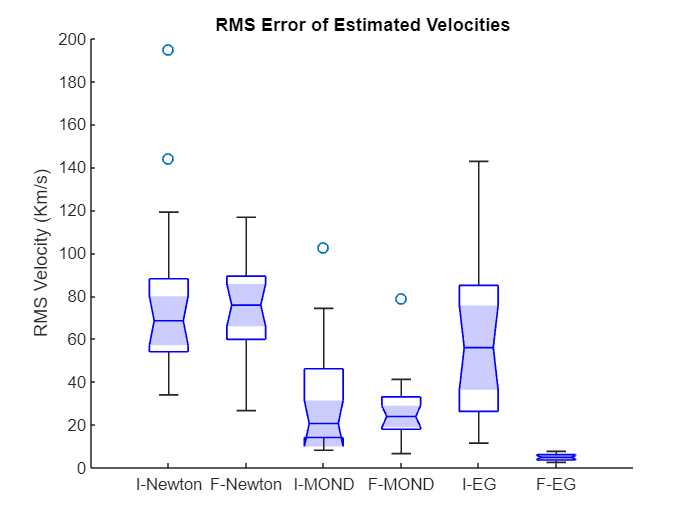


figure(gal+1)
RMSValues = [O_RMS_Newton,RMS_Newton,O_RMS_MOND,RMS_MOND,O_RMS_EG,RMS_EG];
rmsNames = ["I-Newton","F-Newton","I-MOND","F-MOND","I-EG","F-EG"];
b=boxchart(RMSValues,'Notch','on');
b.BoxFaceColor = ["b"];
xticklabels(rmsNames);
ylabel('RMS Velocity (Km/s)');
title("RMS Error of Estimated Velocities");

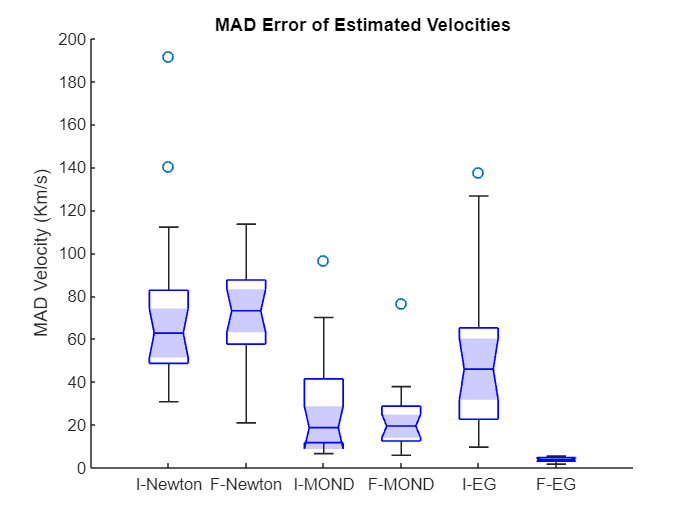

figure(gal+2)
RMSValues = [O_MAD_Newton,MAD_Newton,O_MAD_MOND,MAD_MOND,O_MAD_EG,MAD_EG];
rmsNames = ["I-Newton","F-Newton","I-MOND","F-MOND","I-EG","F-EG"];
b=boxchart(RMSValues,'Notch','on');
b.BoxFaceColor = ["b"];
xticklabels(rmsNames);
ylabel('MAD Velocity (Km/s)');
title("MAD Error of Estimated Velocities");

## The total mass of galaxies

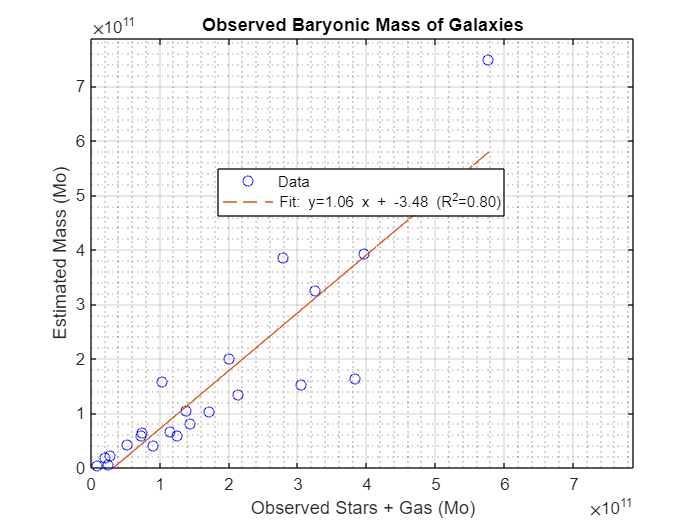

figure(gal+3)
totBaryonicNewton = totGalaxyMass(:,2) + totGalaxyMass(:,3);
totBaryonicEG = totGalaxyMass(:,4) + totGalaxyMass(:,5);

X = [ones(length(totBaryonicNewton),1) totBaryonicNewton];
b = X\totBaryonicEG;
EGCalc2 = X*b;
Rsq2 = 1 - sum((totBaryonicEG - EGCalc2).^2)/sum((totBaryonicEG - mean(totBaryonicEG)).^2);
paramS = sprintf("Fit: y=%4.2f x + %4.2f (R^2=%4.2f)",b(2),b(1)/1.0e10,Rsq2);
plot(totBaryonicNewton,totBaryonicEG,"bo");
hold on
plot(totBaryonicNewton,EGCalc2,'--');
ylabel('Estimated Mass (Mo)');
xlabel('Observed Stars + Gas (Mo)');
title("Observed Baryonic Mass of Galaxies");
legend('Data',paramS,'Location','best');
grid on;
grid minor;
mvalues = 1.05*max([totBaryonicNewton;totBaryonicEG]);
xlim([0, mvalues]);
ylim([0, mvalues]); % Enforce similar range
hold off

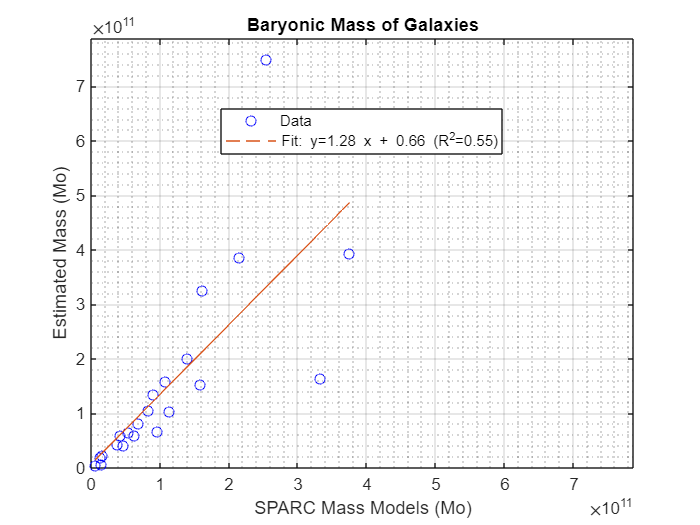

figure(gal+4)
totBaryonicNewton = totGalaxyMass(:,1) + totGalaxyMass(:,3);
totBaryonicEG = totGalaxyMass(:,4) + totGalaxyMass(:,5);

X = [ones(length(totBaryonicNewton),1) totBaryonicNewton];
b = X\totBaryonicEG;
EGCalc2 = X*b;
Rsq2 = 1 - sum((totBaryonicEG - EGCalc2).^2)/sum((totBaryonicEG - mean(totBaryonicEG)).^2);
paramS = sprintf("Fit: y=%4.2f x + %4.2f (R^2=%4.2f)",b(2),b(1)/1.0e10,Rsq2);
plot(totBaryonicNewton,totBaryonicEG,"bo");
hold on
plot(totBaryonicNewton,EGCalc2,'--');
ylabel('Estimated Mass (Mo)');
xlabel('SPARC Mass Models (Mo)');
title("Baryonic Mass of Galaxies");
legend('Data',paramS,'Location','best');
grid on;
grid minor;
mvalues = 1.05*max([totBaryonicNewton;totBaryonicEG]);
xlim([0, mvalues]);
ylim([0, mvalues]); % Enforce similar range
hold off

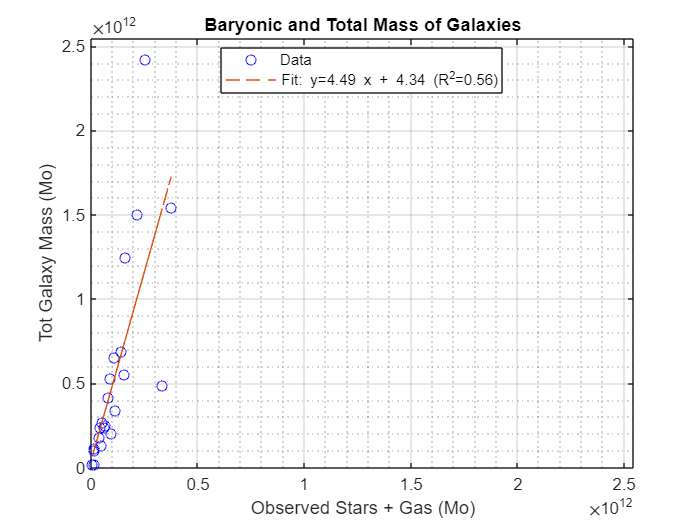

figure(gal+5)
totObsNewton = totGalaxyMass(:,6);

X = [ones(length(totBaryonicNewton),1) totBaryonicNewton];
b = X\totObsNewton;
EGCalc2 = X*b;
Rsq2 = 1 - sum((totObsNewton - EGCalc2).^2)/sum((totObsNewton - mean(totObsNewton)).^2);
paramS = sprintf("Fit: y=%4.2f x + %4.2f (R^2=%4.2f)",b(2),b(1)/1.0e10,Rsq2);
plot(totBaryonicNewton,totObsNewton,"bo");
hold on
plot(totBaryonicNewton,EGCalc2,'--');
ylabel('Tot Galaxy Mass (Mo)');
xlabel('Observed Stars + Gas (Mo)');
title("Baryonic and Total Mass of Galaxies");
legend('Data',paramS,'Location','best');
grid on;
grid minor;
mvalues = 1.05*max([totBaryonicNewton;totObsNewton]);
xlim([0, mvalues]);
ylim([0, mvalues]); % Enforce similar range
hold off

save("SPARC_22_Galaxies.mat");
